**Path Planning**

Set the start and goal pose

% Define Start and Goal Pose
pose_origin = [0 0 0];
pose_1 = [25.5 -3.2 0];
pose_2 = [14 10 pi/3];
pose_3 = [-10.9 1.4 pi/3];

start_pose = pose_origin;
goal_pose = pose_1;

Define the maximum incline angle and convert it to slope

maxinclineangle = 5; % Degrees
maxSlope = tand(maxinclineangle); % Max preferred slope for vehicle

Constuct Z-layer

% Query and store the Z-height
zLayer = mapLayer(flipud(Z),LayerName="Z");

Calculate the gradient and convert to cost

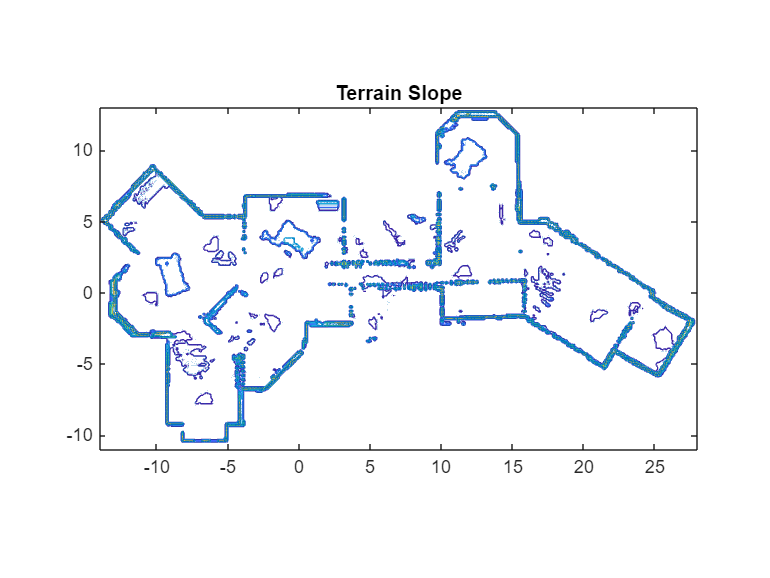

[gx,gy] = gradient(Z);
figure
contour(X,Y,Z)
title("Terrain Slope")
hold on
quiver(X,Y,gx,gy)
axis equal
hold off

Store the gradients

dzdx = mapLayer(flipud(gx),LayerName="dzdx");
dzdy = mapLayer(flipud(gy),LayerName="dzdy");

Calculate the cost and slope

addpath("MapProcessing");
slope2cost = @(x)exampleHelperGradientToCost(maxSlope,flipud(x));
slope = linspace(-2*maxSlope,2*maxSlope,100);
% plot(slope,slope2cost(slope))
% hold on
% xline(maxSlope*[-1 1],"r:")
% yline(1,"b:")
% title("Cost vs Slope")
% xlabel("Slope")
% ylabel("Cost")
% axis square

Calculate costs using the slope function, and store them in map layers.

xCost = mapLayer(slope2cost(gx),LayerName="xCost");
yCost = mapLayer(slope2cost(gy),LayerName="yCost");
diagCost = mapLayer(slope2cost(sqrt(gx.^2+gy.^2)),LayerName="diagCost");

**Terrain Obstacles**

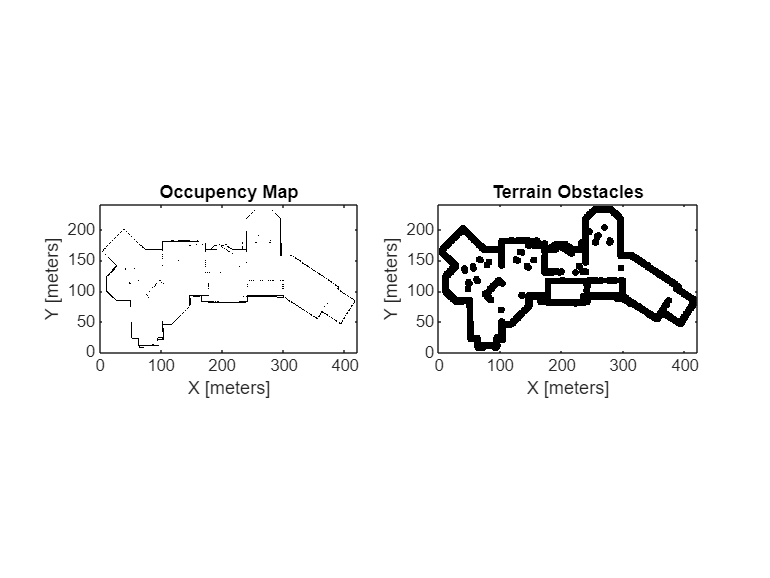

% Initialise obstacle probabilities
% obstacleprob = zeros(y_len, x_len);
occupancy_image = imread('occupency_gmapping.pgm');
imageCropped = occupancy_image(1760-15:2241-15,1580+140:2421+140);
imageCropped = imresize(imageCropped, [241, 421]);
imageNorm = double(imageCropped)/255;
imageOccupancy = 1 - imageNorm;
obstacleprob = imageOccupancy;
% Create custom obstacles
% if isequal(goal_pose, pose_1) && isequal(start_pose, pose_origin)
%     obstacleprob(89:118, 177) = 1;
%     obstacleprob(93:120, 299) = 1;
%     obstacleprob(118, 159:176) = 1;
% elseif isequal(goal_pose, pose_2) && isequal(start_pose, pose_origin)
%     obstacleprob(130:179, 171) = 1;
%     obstacleprob(130, 163:241) = 1;
%     obstacleprob(178, 102:170) = 1;
%     obstacleprob(118, 159:176) = 1;
%     obstacleprob(89:118, 177) = 1;
% end6

% obstacleprob = flipud(obstacleprob);
% Create the binary occupancy map for obstacles
obstacleMap = binaryOccupancyMap(obstacleprob > 0.4, LayerName="obstacles");

% Create the terrain obstacles map without including obstacleMap
terrainObstacles = binaryOccupancyMap(obstacleMap, LayerName="terrainObstacles");

% Inflate the terrain obstacles map
inflate(terrainObstacles, 5);

% Extract map data
obstaclesAndTerrain = double(getMapData(terrainObstacles));

% Slope constraints checking (assuming xCost, yCost, diagCost are defined)
% mInvalidSlope = <your slope constraints logic here>;

% Calculate cells that violate all three slope constraints
mInvalidSlope = xCost > 0.1 & yCost > 0.1 & diagCost > 0.1;

% Block off cells that violate all three slope constraints in the terrain map
obstaclesAndTerrain(mInvalidSlope) = true;

% % Ensure the original obstacles are not included in the terrain map
% originalObstacles = getMapData(obstacleMap);
% obstaclesAndTerrain(originalObstacles) = false;

% Update the terrainObstacles map with the new data
setMapData(terrainObstacles, obstaclesAndTerrain);

% Display the obstacles
figure
show(obstacleMap,Parent=subplot(1,2,1))
title("Occupency Map")
show(terrainObstacles,Parent=subplot(1,2,2))
title("Terrain Obstacles")

**Combine Individual Map Layers**

costMap = multiLayerMap({zLayer dzdx dzdy terrainObstacles xCost yCost diagCost});
xCost.GridOriginInLocal = -xCost.GridSize/xCost.Resolution/2;
% Restore map to original settings
costMap.GridOriginInLocal = [0 0];

% Add helper folders to path
%addpath("Analysis");
%show(visualizationHelper,xCost,subplot(1,3,1),hold="on",title="X Slope",Threshold=1);
%show(visualizationHelper,yCost,subplot(1,3,2),hold="on",title="Y Slope",Threshold=1);
%show(visualizationHelper,diagCost,subplot(1,3,3),hold="on",title="Diagonal Slope",Threshold=1);

**Plan Paths Using 2.5-D Heuristics**

plannerType = "plannerAStarGrid"; % plannerAStarGrid plannerHybridAStar
% Apply map offset
start = [(start_pose(1)-x_offset)/step_size (start_pose(2)-y_offset)/step_size start_pose(3)]; 
goal  = [(goal_pose(1)-x_offset)/step_size (goal_pose(2)-y_offset)/step_size goal_pose(3)];

% If the planner type is plannerAStarGrid, convert the start and goal locations to grid coordinates.
if strcmp(plannerType,"plannerAStarGrid")
    start = world2grid(costMap,start(:,1:2));
    goal  = world2grid(costMap,goal(:,1:2));
end

gWeight = 1;
hWeight = 1;
addpath("Heuristics");
[defaultPlanner,heightAwarePlanner,gradientAwarePlanner,rolloverAwarePlanner] = exampleHelperCreatePlannerObject(plannerType,costMap,gWeight,hWeight);

% Planners return a sequence of IJ cells
paths = cell(4,1);
planningTime = nan(4,1);
tic;
paths{1} = plan(defaultPlanner,start,goal);
planningTime(1) = toc;
paths{2} = plan(heightAwarePlanner,start,goal); 
planningTime(2) = toc-planningTime(1);
paths{3} = plan(gradientAwarePlanner,start,goal); % slope along the path
planningTime(3) = toc-planningTime(2);
paths{4} = plan(rolloverAwarePlanner,start,goal); % slope perpendicular to the path
planningTime(4) = toc-planningTime(3);

if strcmp(plannerType,"plannerHybridAStar")
    for i=1:4
        paths{i} = paths{i}.States;
    end
end

**Define Robot and Scenario Parameters**

% Define simulation parameters
scenarioParams.Gravity = 9.81;    % m/s^2
scenarioParams.UpdateRate = 1/60; % Hz

% Define vehicle parameters for estimating power consumption
scenarioParams.Robot.Mass = 70;     % kg, no payload
scenarioParams.Robot.Velocity = 0.6; % m/s
scenarioParams.Robot.AmpHour = 24;   % A-hr
scenarioParams.Robot.Vnom = 24;                             % V, Voltage
scenarioParams.Robot.RegenerativeBrakeEfficiency = 0;

**Define Performance Metrics**

% Display result
figure
animateResults = true;
pathNames = ["Default","Elevation-Aware Path","Gradient-Aware Path","Rollover-Aware Path"];
addpath("Analysis");
statTable = exampleHelperCalculateMetrics(costMap,scenarioParams,paths,planningTime,pathNames,plannerType)

statTable = 4×8 table
                            Distance (m)    Power (W)    Travel Time (s)    Planning Time (s)    Max Pitch (deg)    Average Pitch (deg)    Max Roll (deg)    Average Roll (deg)
                            ____________    _________    _______________    _________________    _______________    ___________________    ______________    __________________

    Default                     NaN            NaN             NaN              0.051496               NaN                  NaN                 NaN                 NaN        
    Elevation-Aware Path        NaN            NaN             NaN               0.76588               NaN                  NaN                

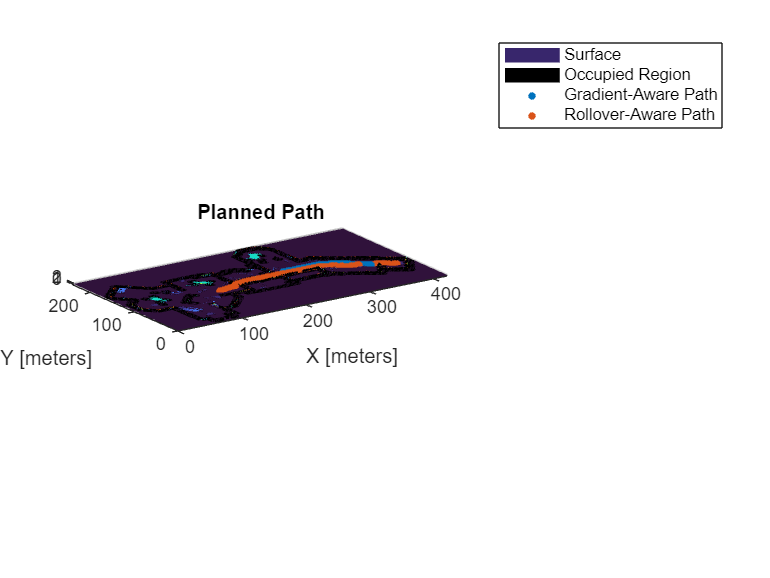

only_gradient = false; % true / false : Whether only show "Gradient-Aware" path
if(only_gradient)
    paths_selected = paths(3);
    pathNames_selected = "Gradient-Aware Path";
else
    paths_selected = paths(3:4);
    pathNames_selected = ["Gradient-Aware Path","Rollover-Aware Path"];
end
exampleHelperVisualizeResults(gca,statTable,scenarioParams,costMap,paths_selected,pathNames_selected,~animateResults,plannerType);

**Apply offset and save the paths**

% If the planner type is plannerAStarGrid, convert the start and goal locations to grid coordinates.
if strcmp(plannerType,"plannerAStarGrid")
    for i = 1:length(paths)
        paths{i} = grid2world(costMap, paths{i}); % Convert each path to world coordinates
    end
end

% clear previous data if there is
clear paths_offset

paths_offset = cell(4,1);
for i = 1:length(paths)
    paths_offset{i}(:, 1) = paths{i}(:, 1)*step_size + x_offset; % Apply x offset
    paths_offset{i}(:, 2) = paths{i}(:, 2)*step_size + y_offset; % Apply y offset
end

% Save the planned paths
save('paths_saved.mat', 'paths_offset');

% for Simulink control model
% set_param('controlling/Inputs/Waypoints Input', 'Value', 'paths_offset{3}');